##  Uncertain System

clc
clearvars -except K;
ts = 1e-3;
N = 20;
a = ureal('a', 1.5, 'PlusMinus', [-.2, .3])

a =   Uncertain real parameter "a" with nominal value 1.5 and variability [-0.2,0.3].


A = diag([-.5 + a, -.4 - a]);
B = [1,1]';
C = [.1, .2];
D = 1;
Gd = ss(A, B, C, D, ts)

Gd =

  Uncertain discrete-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    a: Uncertain real, nominal = 1.5, variability = [-0.2,0.3], 2 occurrences

Type "Gd.NominalValue" to see the nominal value, "get(Gd)" to see all properties, and "Gd.Uncertainty" to interact with the uncertain elements.




systemnames='Gd';
inputvar='[r;u]';
outputvar='[Gd-r;r-Gd]';
input_to_Gd='[u]';
olic=sysic;
%K = musyn(olic, 1, 1); 



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           16.46         16.4        16.44             4
    2           15.78        15.66        15.75            14
    3           15.71        15.66        15.71            18
    4           15.71        15.65        15.72            14

Best achieved robust performance: 15.7



clic = lft(olic, K);
[P, Delta] = lftdata(clic);
A = get(clic).A;
B = get(clic).B;
C = get(clic).C;
D = get(clic).D;

%l-input m-output system; in supervector description l*(N+1) - input
%m*(N+1)-output
l = length(B(1,:));
m = length(C(:,1));
x0 = zeros(length(A),1);
[G, d] = get_G(A, B, C, D, x0, N);
%For IA 


%Inverse System Alg
K0 = inv(G);
beta = .5;
%Steepest Descent
%K0 = G';
%beta = .5/norm(G.Nominal)^2;
L = (eye(m*(N+1)) - beta*G*K0)

L =

  Uncertain matrix with 4 rows and 4 columns.
  The uncertainty consists of the following blocks:
    a: Uncertain real, nominal = 1.5, variability = [-0.2,0.3], 12 occurrences

Type "L.NominalValue" to see the nominal value, "get(L)" to see all properties, and "L.Uncertainty" to interact with the uncertain elements.



[AL,BL,CL,DL, Delta] = get_sert_syst(L);
% blockStr = [-12 0; 4 4]
% [bounds] = mussv(Lsys, blockStr)




%X = sdpvar(1);
X = [sdpvar(1), 0 ; 0 sdpvar(1)]

Linear matrix variable 2x2 (symmetric, real, 2 variables)
Coeffiecient range: 1 to 1


%X = [2 0; 0 .5];

%X = eye(2);
X = kron([-1,0; 0 1], X);

P = sdpvar(length(DL));
Q = sdpvar(length(DL));
P = kron([1 0; 0 -1], P) + kron([0 1; 1 0], Q);


M1 = [eye(length(AL)), zeros(length(AL), length(BL(1,:))); AL, BL]

M1 =    1.000000000000000                   0                   0
                   0   1.000000000000000                   0
                   0                   0   1.000000000000000
   1.000000000000000   0.100000000000000   1.000000000000000


M2 = [CL, DL; zeros(length(DL),length(CL(1,:))), eye(length(DL))];
cnstr = [M1'*X*M1  + M2'*P*M2<=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 3x3|            0.1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++


cnstr = cnstr + [Q - .1 *(eye(2))>=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 3x3|            0.1 to 1|
|   #2|   Matrix inequality 2x2|            0.1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++


cnstr = cnstr + [Q' + Q == 0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|     Matrix inequality 3x3|            0.1 to 1|
|   #2|     Matrix inequality 2x2|            0.1 to 1|
|   #3|   Equality constraint 1x1|              2 to 2|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++




%cnstr = cnstr + [-X + A'*X*A <= 0, A;*X*B]

sol = solvesdp(cnstr) 

SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 4, order n = 8, dim = 16, blocks = 4
nnz(A) = 14 + 0, nnz(ADA) = 16, nnz(L) = 10
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.10E+00 0.000
  1 :   0.00E+00 1.31E+00 0.000 0.2149 0.9000 0.9000   0.71  1  1  1.8E+00
  2 :   0.00E+00 9.83E-02 0.000 0.0749 0.9900 0.9900  -0.09  1  1  5.9E-01
  3 :   0.00E+00 8.29E-03 0.000 0.0843 0.9900 0.9900  -0.98  1  1  6.0E-01
  4 :   0.00E+00 5.37E-04 0.000 0.0648 0.9900 0.9900  -1.00  1  1  6.0E-01
  5 :   0.00E+00 3.39E-05 0.000 0.0631 0.9900 0.9900  -1.00  1  1  6.0E-01
  6 :   0.00E+00 2.11E-06 0.000 0.0623 0.9900 0.9900  -1.00  1  2  6.1E-01
  7 :   0.00E+00 1.30E-07 0.000 0.0616 0.9900 0.9900  -1.00  1  3  6.1E-01
  8 :   0.00E+00 7.92E-09 0.000 0.0609 0.9900 0.9900  -1.00  1  3  6.1E-01
  9 :   0.00E+00 4.77E-10 0.000 0.0602 0.9900 0.9900  -1.00  1  3  6.1E-01

Dual infeasible, 

sol = struct with fields:
    yalmipversion: '20200116'
       yalmiptime: 0.553189100000001
       solvertime: 0.095810900000000
             info: 'Infeasible problem (SeDuMi-1.3)'
          problem: 1


%sol = optimize(cnstr, objective)

p = value(P)

p =    3.944665762373508   0.000000000023333
   0.000000000023333  -3.944665762373508



%%

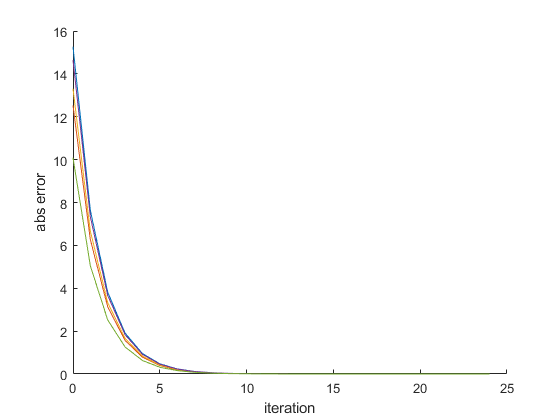

%plot samples

figure
hold on
for i = 1:5
    u0 = rand(4,1);
    r = ones(4,1);
    [A,B,C,D] = ssdata(usample(clic));
    [Gs, ds] = get_G(A,B,C,D,zeros(length(A), 1), N);
    Q = eye(m*(N+1));
    R = eye(l*(N+1));
    
    %Inverse Model
    K0 = inv(Gs);
    %Steepest Descent
    %K0 = Gs';

    [u_inf, e_inf, y_inf, impr, iteration_number] = CGA(Gs,ds, K0,beta,r, u0, 1);
    %[u_inf, e_inf, y_inf, impr, iteration_number] = SDA_suppression_of_evs(Gs,ds, r, u0, R, Q,1);

end
ylabel('abs error')
xlabel('iteration')

hold off

## Solver time for different structures of P

clear all

al = ureal('al', 4);
L = [.1 al; 0 .1];

[AL,BL,CL,DL, Delta] = get_sert_syst(L);
%X = sdpvar(1);
%X = [sdpvar(1), 0 ; 0 sdpvar(1)]
X = [2 0; 0 .5];

X = kron([-1,0; 0 1], X);

P = sdpvar(2);
M1 = [eye(length(AL)), zeros(length(AL), length(BL(1,:))); AL, BL]

M1 =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
    1.0000    0.1000    4.0000


M2 = [CL, DL; zeros(length(DL),length(CL(1,:))), eye(length(DL))];
cnstr = [M1'*X*M1  + M2'*P*M2<=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 3x3|          0.01 to 10|
+++++++++++++++++++++++++++++++++++++++++++++++++++++



sol = solvesdp(cnstr);

The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 4, dim = 10, blocks = 2
nnz(A) = 3 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.77E+00 0.000
  1 :   0.00E+00 1.41E-01 0.000 0.0797 0.9900 0.9900   1.17  1  1  1.3E+00
  2 :   0.00E+00 2.76E-02 0.000 0.1964 0.9000 0.9000   2.25  1  1  4.7E-02
  3 :   0.00E+00 1.63E-04 0.000 0.0059 0.9990 0.9990   1.15  1  1  2.6E-04
  4 :   0.00E+00 1.04E-05 0.000 0.0642 0.9900 0.9900   1.00  1  1  1.6E-05
  5 :   0.00E+00 6.68E-07 0.000 0.0639 0.9900 0.9900   1.00  1  1  1.0E-06
  6 :   0.00E+00 4.25E-08 0.000 0.0637 0.9900 0.9900   1.00  1  1  6.7E-08
  7 :   0.00E+00 2.70E-09 0.000 0.0634 0.9900 0.9900   1.00  1  1  4.2E-09
  8 :   0.00E+00 1.70E-10 0.000 0.0632 0.9900 0.9900   1.00  1  1  2.7E-10

iter seconds digits 

p = value(P);
disp(['solvertime = ', num2str(sol.solvertime)]);

solvertime = 0.632


clear all;
al = ureal('al', 4);
L = [.1 al; 0 .1];
X = [2 0; 0 .5];
X = kron([-1,0; 0 1], X);

[AL,BL,CL,DL, Delta] = get_sert_syst(L);

P = sdpvar(length(DL));
Q = sdpvar(length(DL));
P = kron([1 0; 0 -1], P) %+ kron([0 1; 1 0], Q);

Linear matrix variable 2x2 (symmetric, real, 1 variable)
Coeffiecient range: 1 to 1


M1 = [eye(length(AL)), zeros(length(AL), length(BL(1,:))); AL, BL]

M1 =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
    1.0000    0.1000    4.0000


M2 = [CL, DL; zeros(length(DL),length(CL(1,:))), eye(length(DL))];
cnstr = [M1'*X*M1  + M2'*P*M2<=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 3x3|          0.05 to 10|
+++++++++++++++++++++++++++++++++++++++++++++++++++++


%cnstr = cnstr + [Q - .1 *(eye(2))>=0]
%cnstr = cnstr + [Q' + Q == 0]


%cnstr = cnstr + [-X + A'*X*A <= 0, A;*X*B]

sol = solvesdp(cnstr);

SeDuMi 1.3.4 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 4, dim = 10, blocks = 2
nnz(A) = 1 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.76E+00 0.000
  1 :   0.00E+00 1.40E-01 0.000 0.0797 0.9900 0.9900   1.17  1  1  1.3E+00
  2 :   0.00E+00 2.75E-02 0.000 0.1964 0.9000 0.9000   2.25  1  1  4.7E-02
  3 :   0.00E+00 1.62E-04 0.000 0.0059 0.9990 0.9990   1.15  1  1  2.6E-04
  4 :   0.00E+00 1.04E-05 0.000 0.0642 0.9900 0.9900   1.00  1  1  1.6E-05
  5 :   0.00E+00 6.65E-07 0.000 0.0639 0.9900 0.9900   1.00  1  1  1.0E-06
  6 :   0.00E+00 4.23E-08 0.000 0.0637 0.9900 0.9900   1.00  1  1  6.7E-08
  7 :   0.00E+00 2.68E-09 0.000 0.0634 0.9900 0.9900   1.00  1  1  4.2E-09
  8 :   0.00E+00 1.69E-10 0.000 0.0632 0.9900 0.9900   1.00  1  1  2.7E-10

iter seconds digits       c*x               b*y
  8      1.2   Inf -7.0304679689e-11  0.0000000

p = value(P);
disp(['solvertime = ', num2str(sol.solvertime)]);

solvertime = 0.73523
